# Multi-link pendulum system: Simscape modeling

Input system parameters:

%% PENDULUM PARAMETERS %%
init_angle=90   % Initial angle from vertical (degrees)

init_angle = 90

n_links=2       % Number of links 

n_links = 2


L=60;           % Total length of pendulum (cm)
W=2;            % Width of links (cm)
H=2;            % Depth of links (cm)
damping=0.005;     % Damping factor at joints (N*m/(deg/s))
spring=0.01;    % Torsional spring constant (N*m/deg)

base_damping= 0.000001;

%% MEASUREMENT PARAMETERS %%
coord_noise_std=0;
angle_noise_std=0;

%% SIMULATION PARAMETERS %%
sim_steps = 500;
dt = 0.01;
t = [0:dt:dt*(sim_steps-1)]';
n_sims = 60;
torque_gain = 0.01;
total_sim_time = sim_steps*dt*n_sims / 60

total_sim_time = 5

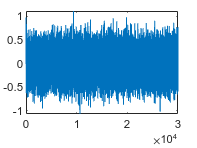


% Generate a sequence of random numbers with a normal distribution
samples = 0:1:(sim_steps*n_sims);  % time vector
x = normrnd(0,0.25,size(samples));

% Interpolate the sequence to create a continuous signal
t_interp = 0:0.001:(sim_steps*n_sims);  % interpolated time vector
rand_torque = interp1(samples, x, t_interp, 'spline');  % interpolate using cubic spline
plot(t_interp, rand_torque)

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','through');
end

data_len = (sim_steps-1)*n_sims

data_len = 29940


in_torque = zeros(data_len, 1);

in_ex = zeros(data_len, 1);
in_ez = zeros(data_len, 1);
in_phi = zeros(data_len, 1);

out_ex = zeros(data_len, 1);
out_ez = zeros(data_len, 1);
out_phi = zeros(data_len, 1);

in_edx = zeros(data_len, 1);
in_edz = zeros(data_len, 1);
in_dphi = zeros(data_len, 1);
in_dtheta = zeros(data_len, 1);
in_theta = zeros(data_len, 1);

out_edx = zeros(data_len, 1);
out_edz = zeros(data_len, 1);
out_dphi = zeros(data_len, 1);
out_dtheta = zeros(data_len, 1);
out_theta = zeros(data_len, 1);

% Simulate model
for sim_n=1:n_sims
    log_indices = (sim_n-1)*(sim_steps-1)+1:sim_n*(sim_steps-1);
    torque_indices = (sim_n-1)*sim_steps+1:sim_n*sim_steps;
    torque = timeseries(rand_torque(torque_indices), t);

    init_angle = min(max(normrnd(0, 90), -180), 180);

    simout = sim("pendulum_system.slx", t);
    
    % This is quite long but hopefully clear what is being set up

    % 0 at top, positive anticlockwise, 0->2pi range
    phi = simout.pendulum_angle;  
    % Centre 0, positive right
    ex = simout.end_x;  
    % Centre 0, positive upwards
    ez = simout.end_z;  

    in_torque(log_indices) = rand_torque(torque_indices(1:length(torque_indices)-1));
    % 0 at top, positive anticlockwise, -pi->pi range
    in_phi(log_indices) = wrapTo2Pi(phi(1:sim_steps-1) + pi) - pi;
    in_ex(log_indices) = ex(1:sim_steps-1);
    in_ez(log_indices) = ez(1:sim_steps-1);
    
    % 0 at top, positive anticlockwise, -pi->pi range
    out_phi(log_indices) = wrapTo2Pi(phi(2:sim_steps) + pi) - pi;    
    out_ex(log_indices) = ex(2:sim_steps);
    out_ez(log_indices) = ez(2:sim_steps);

    r = sqrt(ex.^2 + ez.^2);
    % 0 at top, positive anticlockwise
    theta = atan2(ez, ex) - pi/2;

    % dphi = gradient(phi);
    phi_ext = [phi(1); phi];
    dphi_ext = phi_ext(2:sim_steps+1) - phi_ext(1:sim_steps);
    dphi = atan2(sin(dphi_ext),cos(dphi_ext));
    dex = gradient(ex);
    dez = gradient(ez);
    % der = gradient(er);
    % dr = gradient(r);
    % dtheta = gradient(theta);
    theta_ext = [theta(1); theta];
    dtheta_ext = theta_ext(2:sim_steps+1) - theta_ext(1:sim_steps);
    dtheta = atan2(sin(dtheta_ext),cos(dtheta_ext));

    in_dphi(log_indices) = dphi(1:sim_steps-1);
    in_edx(log_indices) = dex(1:sim_steps-1);
    in_edz(log_indices) = dez(1:sim_steps-1);
    in_dtheta(log_indices) = dtheta(1:sim_steps-1);
    in_theta(log_indices) = theta(1:sim_steps-1);

    out_dphi(log_indices) = dphi(2:sim_steps);
    out_edx(log_indices) = dex(2:sim_steps);
    out_edz(log_indices) = dez(2:sim_steps);
    out_dtheta(log_indices) = dtheta(2:sim_steps);
    out_theta(log_indices) = theta(2:sim_steps);
end

% phi decomposed into sin(phi) and cos(phi) for continuous domain
% invert by atan2(sin(phi),cos(phi)) => gives 0 at top, -pi->pi range
nn_input = cat(2, ...
    sin(in_phi), cos(in_phi), sin(in_theta), cos(in_theta), in_ex, in_ez, ...
    in_dphi, in_edx, in_edz, in_dtheta, in_torque);

nn_targets = cat(2, ...
    sin(out_phi), cos(out_phi), sin(out_theta), cos(out_theta), out_ex, out_ez, ...
    out_dphi, out_edx, out_edz, out_dtheta);

% Train the network, name it dynamics
dynamics_train

performance = 4.1692e-06

trainPerformance = 4.9514e-06

valPerformance = 2.3404e-06

testPerformance = 2.3473e-06

 
MATLAB function generated: dynamics.m
To view generated function code: edit dynamics
For examples of using function: help dynamics
 


% Perform rollout of dynamics model and compare to simulation

% Input desired starting position below:
initial_phi = -pi/4;

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','through');
end

t = [0:dt:dt*(sim_steps-1)]';
init_angle = rad2deg(initial_phi);
torque_indices = 1:sim_steps;
% torque = timeseries(zeros(sim_steps,1), t);
torque = timeseries(0.1*ones(sim_steps,1), t);
real = sim("pendulum_system.slx", t);
% 0 at top, positive anticlockwise, 0->2pi
phi = real.pendulum_angle;    

phi0 = phi(1)

phi0 = -0.7854

ex0 = real.end_x(1)

ex0 = 0.4243

ez0 = real.end_z(1)

ez0 = 0.4243

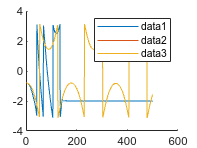


initial_state = [sin(initial_phi),cos(initial_phi),sin(initial_phi), cos(initial_phi), ex0,ez0,0,0,0,0]';
initial_action = [0.0];
state = dynamics(cat(1, initial_state, initial_action));
rollout_phi = zeros(sim_steps,1);
rollout_x = zeros(sim_steps, 1);
rollout_y = zeros(sim_steps, 1);

rollout_phi(1) = atan2(state(1),state(2));
rollout_x(1) = state(2);
rollout_y(1) = state(3);

for sim_step=2:sim_steps
    state = dynamics(cat(1,state,initial_action));
    rollout_phi(sim_step) = atan2(state(1),state(2));
    rollout_x(sim_step) = state(2);
    rollout_y(sim_step) = state(3);

end

clf
hold on;
plot(rollout_phi);
plot(wrapTo2Pi(phi+pi)-pi);
plot(atan2(sin(phi),cos(phi)))
legend();
hold off;